# Image Restoration - Deconvolution

## Part A

## Adding Noise to Image

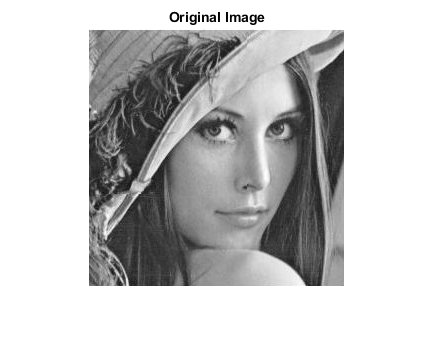


lenna = imread("lenna.jpg");
%Keeping only one channel
lenna =lenna(:,:,1);
f1 = figure;
imshow(lenna);
title("Original Image");


[rows,columns] = size(lenna);

% Adding white Gaussian noise such that SNR = 10 dB.
%Noise Formula
%dNoise = d + sqrt(10^(SNR/10)) * randomPixels = variance * randomPixels
%SNR = Psignal/Pnoise, for Psignal I use the mean intensity of the image.
SNR = 10;

Psignal = sum(sum(double(lenna(:,:)).^ 2)) / (rows * columns);

%Calculating noise variance
variance = sqrt(Psignal / 10 ^(SNR/10));

%Additive White Gaussian Noise calculation and adding to signal
AWGN(:,:) = variance * randn(rows,columns);
noisyLenna = double(lenna) + AWGN;
% g = f + n;


## Denoising with Wiener Filter

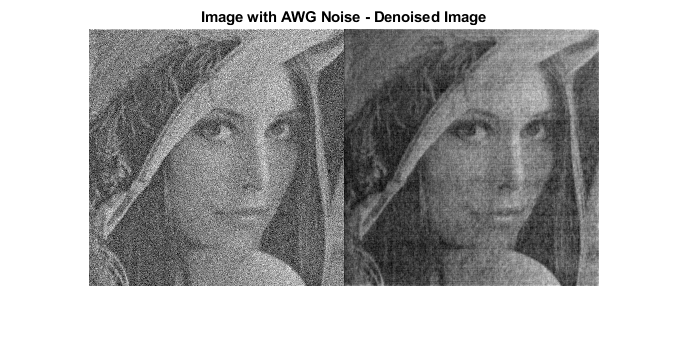

% Using the knowledge we have about the noise
% Power of noise signal
Pnoise = abs(fft2(AWGN)).^2 /(rows*columns) ;

%Power of image signal + noise signal
PnoisyImage = abs(fft2(noisyLenna)).^2 /(rows*columns) ;

%Power of image signal without noise
Pimage = PnoisyImage - Pnoise;

%Calculating Wiener Filter
Hwiener = uint8(255 * (Pimage ./ PnoisyImage));
hwiener = ifft2(Hwiener);

%Zero padding for 2N*2N

ExtendedNoisyImage = zeros(2*rows,2*columns);
ExtendedNoisyImage(1:rows,1:columns) = noisyLenna;

Gextended = fft2(ExtendedNoisyImage);

PaddedFilter = zeros(2*rows,2*columns);
PaddedFilter(1:rows,1:columns) = hwiener;
HwienerExtended = fft2(PaddedFilter);

%Calculating Pointwise product of Gextended and HwienerExtended
ExtendedImage = HwienerExtended .* Gextended;

%IFFT2 for calculating final denoised image
finalExtendedImage = ifft2(ExtendedImage);
finalImage = finalExtendedImage(1:rows,1:columns);

f2 = figure('Name','Using the knowledge about the noise');
imshowpair(noisyLenna,finalImage,'montage');
title("Image with AWG Noise - Denoised Image");

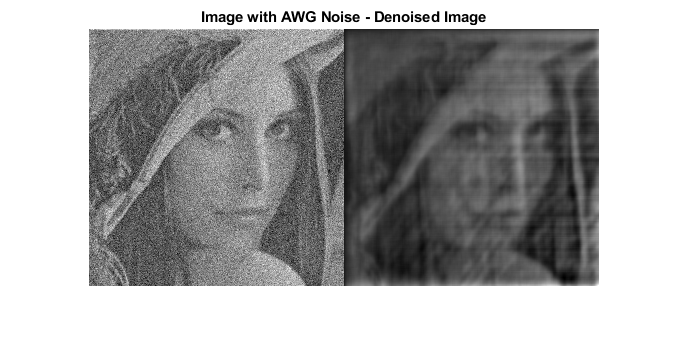

%% Not knowing anything about the noise
% Using the mean value of a window that covers some of the high
% frequencies of the noisy image G


G = fft2(noisyLenna);

hFWindow = G(200:255,200:255);
Pnoise = mean(abs(hFWindow(:)));

%Power of image without noise
Pimage = PnoisyImage - Pnoise;

%Calculating Wiener Filter
Hwiener = uint8(255 * (Pimage ./ PnoisyImage));
hwiener = ifft2(Hwiener);

%Zero padding for 2N*2N

ExtendedNoisyImage = zeros(2*rows,2*columns);
ExtendedNoisyImage(1:rows,1:columns) = noisyLenna;

Gextended = fft2(ExtendedNoisyImage);

PaddedFilter = zeros(2*rows,2*columns);
PaddedFilter(1:rows,1:columns) = hwiener;
HwienerExtended = fft2(PaddedFilter);

%Calculating Pointwise product of Gextended and HwienerExtended
ExtendedImage = HwienerExtended .* Gextended;

%IFFT2 for calculating final denoised image
finalExtendedImage = ifft2(ExtendedImage);
finalImage = finalExtendedImage(1:rows,1:columns);

f2 = figure('Name','Not knowing the noise');
imshowpair(noisyLenna,finalImage,'montage');
title("Image with AWG Noise - Denoised Image");

## Part B - Denoising random noise

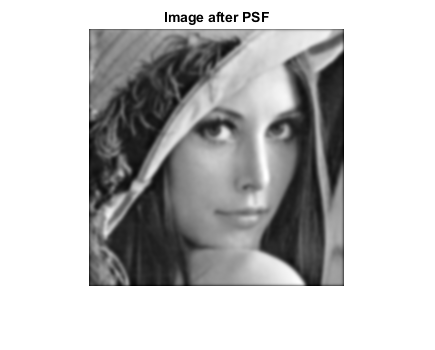

%Applying Point Spread Function to image
psfImage = psf(lenna);

f3 = figure('Name','Image after PSF');
imshow(psfImage,[]);
title("Image after PSF");

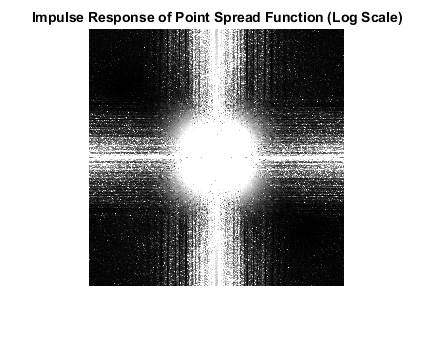

freqPSF = fft2(psfImage);
freqLenna = fft2(lenna);
PSFimpulseResponse = freqPSF ./ freqLenna;


f4 = figure('Name','Impulse response of PSF');
imshow(log(1+abs(fftshift(PSFimpulseResponse))));
title('Impulse Response of Point Spread Function (Log Scale)');

## Inverse Filtering with threshold

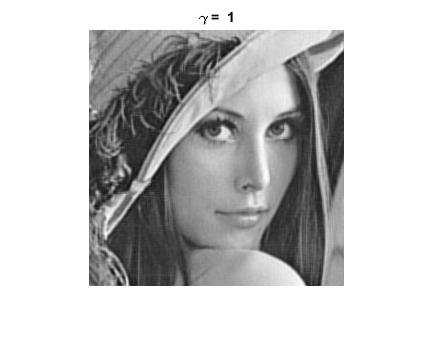

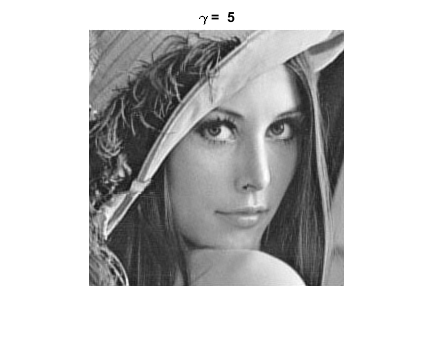

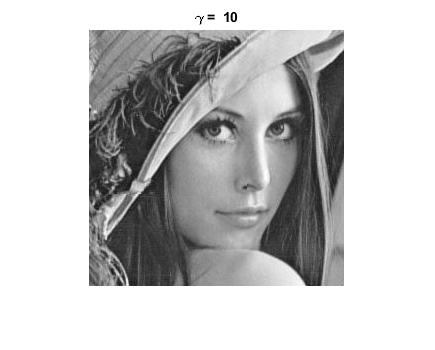

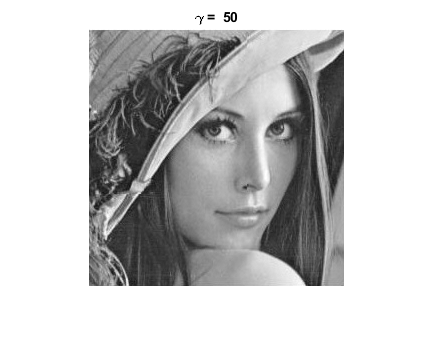

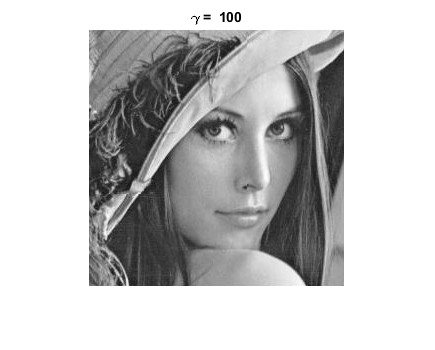

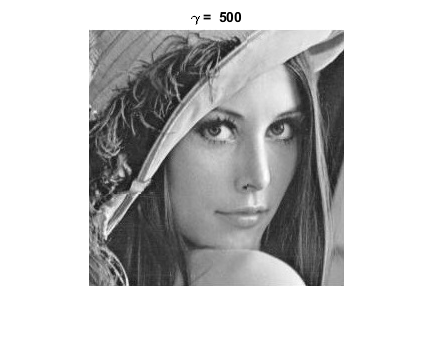

thresholdValues=[1 5 10 50 100 500];
inverseFilter=zeros(rows,columns);
MSE = zeros(size(thresholdValues));
cnt = 0;
%For different γ values
for g = thresholdValues
    cnt = cnt + 1;
    for u=1:rows
        for v=1:columns
            if (1/abs(PSFimpulseResponse(u,v)) < g)
                inverseFilter(u,v) = 1/PSFimpulseResponse(u,v);
            else
                inverseFilter(u,v)=g*abs(PSFimpulseResponse(u,v))/PSFimpulseResponse(u,v);
            end
        end
    end
    
    restoredImageFreq = inverseFilter.* freqPSF ;
    restoredImage = ifft2(restoredImageFreq);
    
      

    figure
    imshow(uint8(restoredImage))
    title("\gamma =  " + g)


    MSE(cnt) = sum(sum((double(lenna)-double(restoredImage)).^2)) / rows * columns;
   
end

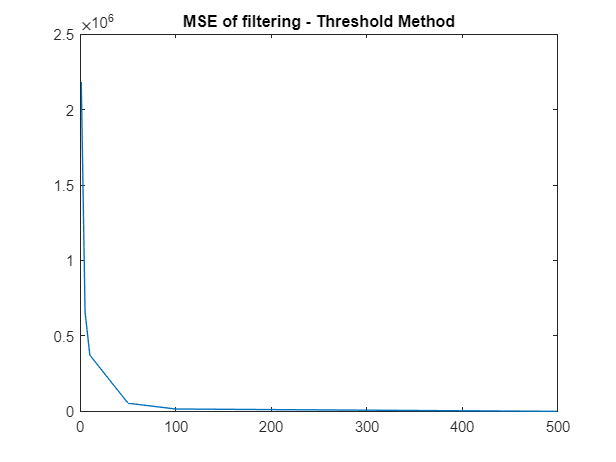



%Plotting the Mean Square Error for different threshold values
f3 = figure;
plot(thresholdValues,MSE)
title("MSE of filtering - Threshold Method");

## Inverse Filtering Without Threshold

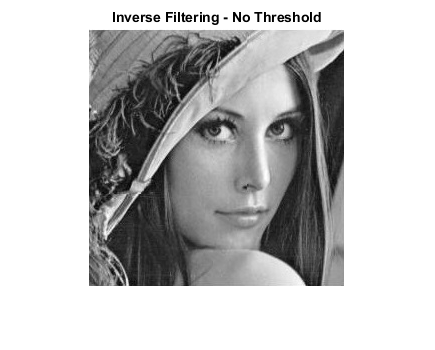

inverseFilter = 1 ./ PSFimpulseResponse;

restoredImageFreq2 = inverseFilter.* freqPSF ;
restoredImage2 = ifft2(restoredImageFreq);

f4 = figure;
imshow(restoredImage2,[]);

title("Inverse Filtering - No Threshold");